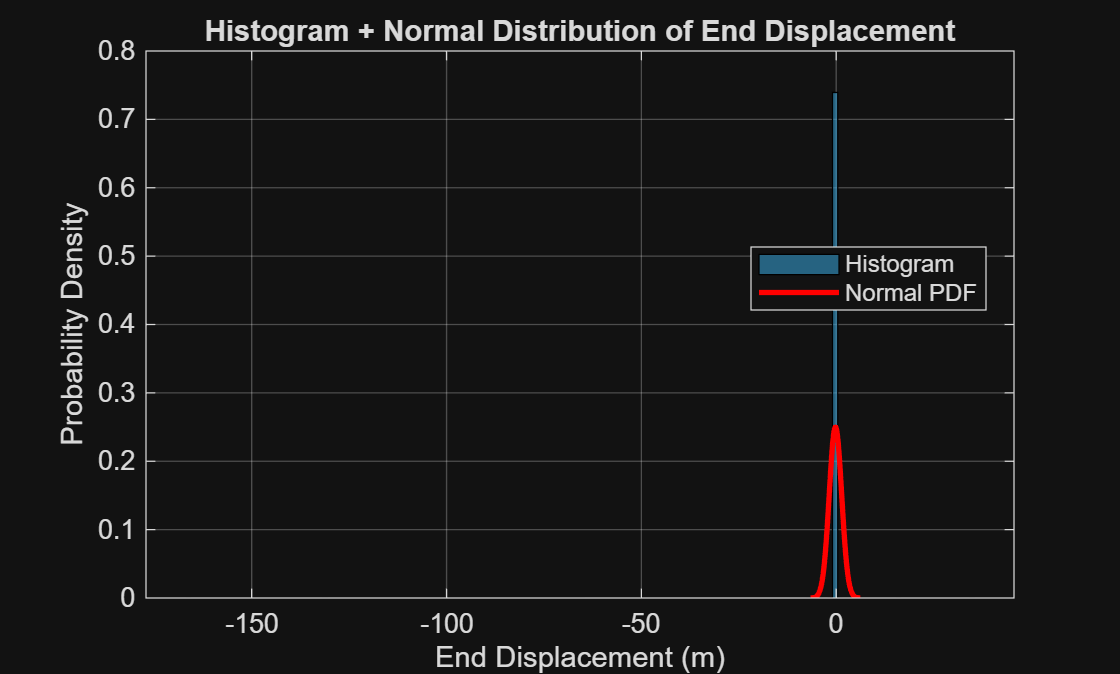

clc;
clear all;

number_of_runs = 20000;

%% Beam parameters
L_beam = 10;            
N = 5;                  
Nodes = N + 1;          
partLength = L_beam / N;

%% Random input parameters (using mvnrnd)
EI_mu = 210e9 * 2e-4 * ones(N,1);         
EI_COV = 0.3;                             
EI_std = EI_COV * EI_mu;                 

% Correlation matrix setup
corr_val = 0.3;
CorrMatrix = eye(N);
for i = 1:N
    for j = 1:N
        if abs(i - j) == 1
            CorrMatrix(i, j) = corr_val;
        elseif abs(i - j) > 1
            CorrMatrix(i, j) = 0;
        end
    end
end

% Covariance matrix
D = diag(EI_std);
Cov_EI = D * CorrMatrix * D;

% Generate EI samples
EI_samples = mvnrnd(EI_mu, Cov_EI, number_of_runs);

% Load
P = 20000;

% Preallocate
end_displacement = zeros(number_of_runs, 1);
mean_vals = zeros(number_of_runs, 1);
std_vals = zeros(number_of_runs, 1);

%% Monte Carlo Simulation
for n = 1:number_of_runs
    EI = EI_samples(n, :);  % 1xN

    % DOF mapping
    dof = zeros(N, 4);
    for i = 1:N
        dof(i,:) = [2*i - 1, 2*i, 2*i + 1, 2*i + 2];
    end

    % Global stiffness matrix
    Keq = zeros(Nodes*2);
    for i = 1:N
        Le = partLength;
        k = (EI(i) / Le^3) * ...
            [12, 6*Le, -12, 6*Le;
             6*Le, 4*Le^2, -6*Le, 2*Le^2;
            -12, -6*Le, 12, -6*Le;
             6*Le, 2*Le^2, -6*Le, 4*Le^2];

        for j = 1:4
            for p = 1:4
                Keq(dof(i,j), dof(i,p)) = Keq(dof(i,j), dof(i,p)) + k(j,p);
            end
        end
    end

    % External load at DOF 11
    F = zeros(Nodes*2, 1);
    F(11) = -P;

    % Boundary conditions
    fixed_dofs = [1, 2];
    free_dofs = setdiff(1:Nodes*2, fixed_dofs);

    % Solve
    K_reduced = Keq(free_dofs, free_dofs);
    F_reduced = F(free_dofs);
    d = zeros(Nodes*2, 1);
    d(free_dofs) = K_reduced \ F_reduced;

    % Store displacement
    end_displacement(n) = d(11);

    % Running stats
    mean_vals(n) = mean(end_displacement(1:n));
    std_vals(n) = std(end_displacement(1:n));
end

% Calculate statistics
mu_d = mean(end_displacement);
sigma_d = std(end_displacement);

% Define tighter x range: ±4σ
x = linspace(mu_d - 4*sigma_d, mu_d + 4*sigma_d, 1000);
pdf_normal = normpdf(x, mu_d, sigma_d);

% Freedman-Diaconis bin width (optional)
iqr_val = iqr(end_displacement);
bin_width = 2 * iqr_val / (number_of_runs)^(1/3);

% --- Histogram + Normal PDF ---
mu_d = mean(end_displacement);
sigma_d = std(end_displacement);
x = linspace(mu_d - 4*sigma_d, mu_d + 4*sigma_d, 100);
pdf_values = normpdf(x, mu_d, sigma_d);

figure;
histogram(end_displacement, 150, 'Normalization', 'pdf', ...
    'FaceColor', [0.2 0.6 0.8], 'EdgeColor', 'k', 'DisplayName', 'Histogram');
hold on;
plot(x, pdf_values, 'r-', 'LineWidth', 2, 'DisplayName', 'Normal PDF');
xlabel('End Displacement (m)');
ylabel('Probability Density');
title('Histogram + Normal Distribution of End Displacement');
legend('Location', 'best');
grid on;

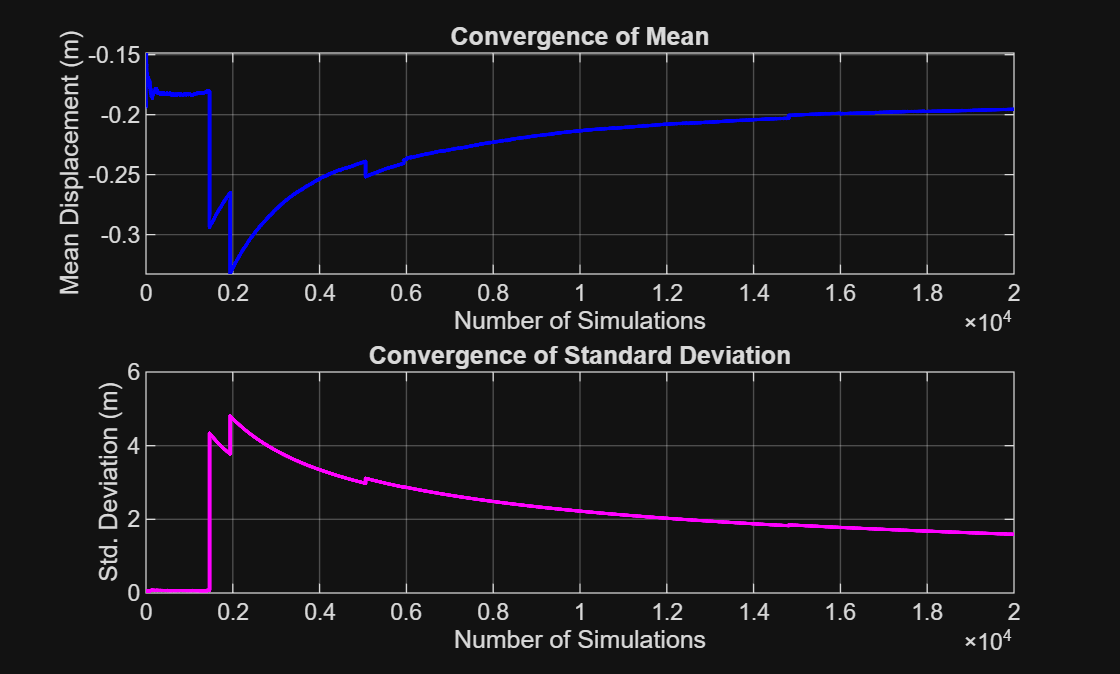



%% --- Plot 2: Convergence of Mean and Std Dev ---
figure;
subplot(2,1,1)
plot(1:number_of_runs, mean_vals, 'b', 'LineWidth', 1.5);
xlabel('Number of Simulations');
ylabel('Mean Displacement (m)');
title('Convergence of Mean');
grid on;

subplot(2,1,2)
plot(1:number_of_runs, std_vals, 'm', 'LineWidth', 1.5);
xlabel('Number of Simulations');
ylabel('Std. Deviation (m)');
title('Convergence of Standard Deviation');
grid on;


%% --- Final Output ---
fprintf('Final Mean of End Displacement: %.6f m\n', mu_d);

Final Mean of End Displacement: -0.195490 m


fprintf('Final Std Dev of End Displacement: %.6f m\n', sigma_d);

Final Std Dev of End Displacement: 1.594257 m
